clear
FFTSize = 4096;
hopsize = 2048;
overlapp = FFTSize -hopsize;

[signal,Fs] = audioread('AudioTest\BADSISTA_midi_BADSISTA_midi_bass_loop_agora_135_Dmin.wav');
signal = signal(:,1) % signal = toutes les lignes de la première colonne

signal =     0.0003
    0.0008
    0.0014
    0.0019
    0.0025
    0.0032
    0.0042
    0.0052
    0.0066
    0.0080




[FFTVector,frequencyBand,newTime] = spectrogram (signal,FFTSize,overlapp,FFTSize-1,Fs,'yaxis')

FFTVector = 	1.0e+02 *

   0.0026 + 0.0000i  -0.0020 + 0.0000i  -0.0011 + 0.0000i   0.0013 + 0.0000i  -0.0018 + 0.0000i   0.0046 + 0.0000i  -0.0053 + 0.0000i   0.0019 + 0.0000i   0.0014 + 0.0000i   0.0001 + 0.0000i  -0.0015 + 0.0000i  -0.0011 + 0.0000i   0.0017 + 0.0000i  -0.0027 + 0.0000i  -0.0007 + 0.0000i   0.0093 + 0.0000i  -0.0108 + 0.0000i   0.0027 + 0.0000i   0.0021 + 0.0000i   0.0014 + 0.0000i  -0.0050 + 0.0000i   0.0009 + 0.0000i   0.0015 + 0.0000i   0.0010 + 0.0000i  -0.0019 + 0.0000i   0.0013 + 0.0000i  -0.0043 + 0.0000i   0.0034 + 0.0000i   0.0006 + 0.0000i  -0.0013 + 0.0000i   0.0100 + 0.0000i   0.0215 + 0.0000i  -0.0118 + 0.0000i  -0.0035 + 0.0000i   0.0012 + 0.0000i   0.0024 + 0.0000i  -0.0005 + 0.0000i  -0.0012 + 0.0000i   0.0005 + 0.0000i   0.0008 + 0.0000i  -0.0008 + 0.0000i   0.0019 + 0.0000i  -0.0065 + 0.0000i  -0.0001 + 0.0000i  -0.0078 + 0.0000i   0.0057 + 0.0000i  -0.0009 + 0.0000i  -0.0092 + 0.0000i   0.0047 + 0.0000i   0.0035 + 0.0000i
   0.0093 - 0.0117i   0.0

frequencyBand = 	1.0e+04 *

         0
    0.0012
    0.0023
    0.0035
    0.0047
    0.0059
    0.0070
    0.0082
    0.0094
    0.0105


newTime =     0.0427    0.0853    0.1280    0.1707    0.2133    0.2560    0.2987    0.3413    0.3840    0.4267    0.4693    0.5120    0.5547    0.5973    0.6400    0.6827    0.7253    0.7680    0.8107    0.8533    0.8960    0.9387    0.9813    1.0240    1.0667    1.1093    1.1520    1.1947    1.2373    1.2800    1.3227    1.3653    1.4080    1.4507    1.4933    1.5360    1.5787    1.6213    1.6640    1.7067    1.7493    1.7920    1.8347    1.8773    1.9200    1.9627    2.0053    2.0480    2.0907    2.1333



%compute spectral HFC diff
HFCLocal = zeros(1,size(FFTVector,2))

HFCLocal =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


HFCDiff = zeros(1,size(FFTVector,2))

HFCDiff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


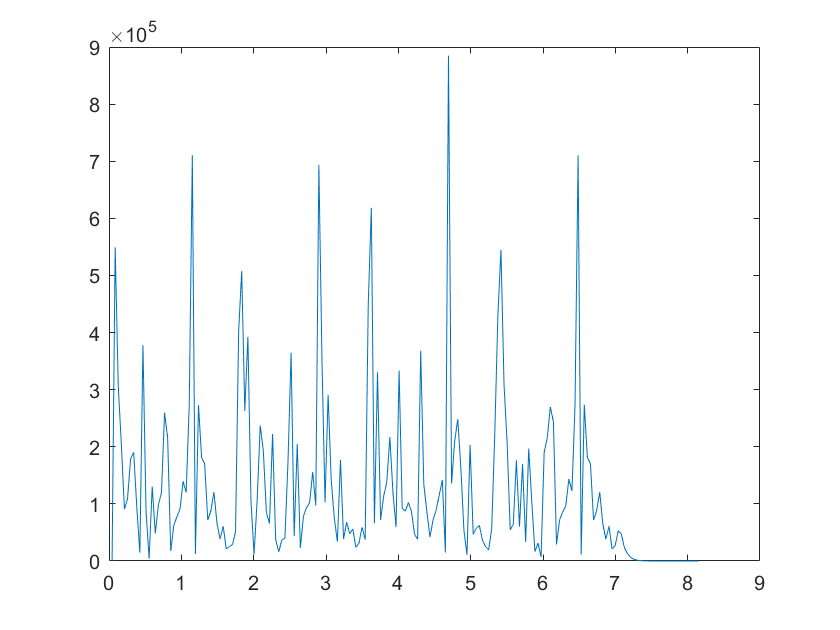

for i=1:size(FFTVector,2)
    for y=1:size(FFTVector,1)
        HFCLocal(1,i) = HFCLocal(1,i) + y* abs(FFTVector(y,i))*abs(FFTVector(y,i));
    end
end

for i =2:size(HFCDiff,2)
    HFCDiff(1,i) = abs(HFCLocal(1,i)-HFCLocal(1,i-1));
end

plot(newTime,HFCDiff);


%compute threshold and movmean
meanNbr = 10;
[pks,locs] = findpeaks(HFCDiff)

pks = 	1.0e+05 *

    5.4942    1.9014    3.7775    1.3037    2.5950    1.3965    7.1040    2.7297    1.2063    0.6084    5.0775    3.9269    2.3739    2.2225    3.6467    2.0490    1.5557    6.9352    2.9079    1.7708    0.6784    0.5602    0.5910    6.1845    3.3055    2.1704    3.3352    1.0233    3.6818    1.4177    8.8492    2.4834    2.0328    0.6222    5.4490    1.7655    1.6970    1.9688    0.3141    2.6965    1.4354    7.1033    2.7368    1.2062    0.6082    0.5283


locs =      2     8    11    14    18    24    27    29    34    37    43    45    49    53    59    61    66    68    71    75    77    79    82    85    87    91    94    97   101   108   110   113   117   120   127   132   134   136   139   143   149   152   154   159   162   165


median = movmedian(HFCDiff,meanNbr)

median = 	1.0e+05 *

    2.0409    1.5652    1.7891    1.8453    1.7891    1.4393    1.8453    1.4393    1.0176    1.0176    1.0176    0.9658    0.9658    0.9658    1.0893    1.0893    0.9287    0.8804    0.9460    0.9460    1.0893    1.1968    1.2987    1.0535    1.0535    1.2987    1.5483    1.5483    1.5483    1.4532    1.4532    1.0427    0.7989    0.7989    0.6869    0.6318    0.5609    0.5609    0.5609    0.5609    0.5609    0.8315    0.7840    1.0557    1.7154    2.1534    2.1534    1.4948    1.4948    1.0557


threshold = median + movmean(HFCDiff,meanNbr)

threshold = 	1.0e+05 *

    4.3422    3.6645    3.8441    3.8811    3.7038    3.1770    3.9607    3.0925    2.3689    2.2952    2.2526    2.1904    2.1308    2.2001    2.4451    2.4480    1.9721    1.9141    2.0661    2.0754    2.2904    2.5726    3.2656    2.7729    2.8299    3.2389    3.5960    3.5903    3.5876    3.4735    3.4189    2.7736    1.8802    1.8892    1.5294    1.3219    1.1323    1.4611    1.8810    2.0230    2.3502    2.6879    2.5914    2.9478    3.8197    4.4222    4.4557    3.4622    3.1767    2.5130




realpks = zeros(1,size(pks,2))

realpks =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


realLocs = zeros(1,size(locs,2))

realLocs =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


index=1

index = 1

for i =1 : size(pks,2)
    if pks(i) > threshold(locs(1,i))
        realpks(index) = pks(1,i);
        realLocs(index) = locs(1,i);
        index= index+1;
    end
end
index

index = 21

realpksResized = zeros(1,index-1);
realpksResized = realpks(1:index-1)

realpksResized = 	1.0e+05 *

    5.4942    3.7775    2.5950    7.1040    5.0775    3.9269    2.2225    3.6467    2.0490    6.9352    1.7708    6.1845    3.3352    3.6818    8.8492    2.0328    5.4490    1.9688    2.6965    7.1033


realLocsResized = zeros(1,index-1);
realLocsResized = realLocs(1:index-1)

realLocsResized =      2    11    18    27    43    45    53    59    61    68    75    85    94   101   110   117   127   136   143   152


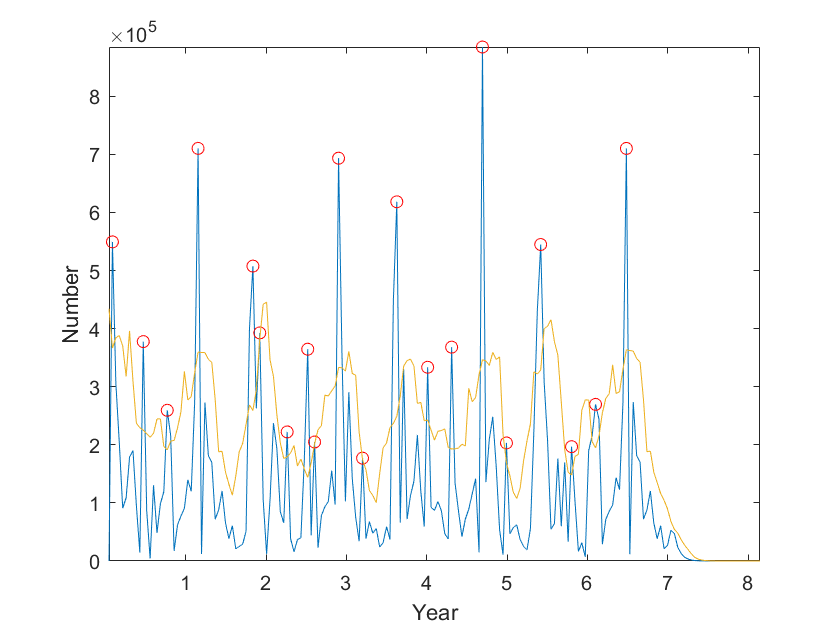

plot(newTime,HFCDiff,newTime(realLocsResized),realpksResized,'or')
xlabel('Year')
ylabel('Number')
axis tight
hold on;
plot(newTime,threshold)
hold off;



[x0,y0,iout,jout] = intersections(newTime,HFCDiff,newTime,threshold)

x0 =     0.0727
    0.1152
    0.4516
    0.4922
    0.7481
    0.8127
    1.1147
    1.1734
    1.7742
    1.8725


y0 = 	1.0e+05 *

    3.8654
    3.7903
    2.2703
    2.2193
    1.9412
    2.0666
    3.2839
    3.5931
    2.5468
    2.9070


iout =     1.7035
    2.7005
   10.5851
   11.5362
   17.5337
   19.0471
   26.1261
   27.5027
   41.5821
   43.8857


jout =     1.7035
    2.7005
   10.5851
   11.5362
   17.5337
   19.0471
   26.1261
   27.5027
   41.5821
   43.8857


realpks

realpks = 	1.0e+05 *

    5.4942    3.7775    2.5950    7.1040    5.0775    3.9269    2.2225    3.6467    2.0490    6.9352    1.7708    6.1845    3.3352    3.6818    8.8492    2.0328    5.4490    1.9688    2.6965    7.1033         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


realLocs

realLocs =      2    11    18    27    43    45    53    59    61    68    75    85    94   101   110   117   127   136   143   152     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


index2 =1

index2 = 1